% a) run Lanczos-Verfahren
rng(0); %seed
N = 10

N = 10

m = 50

m = 50

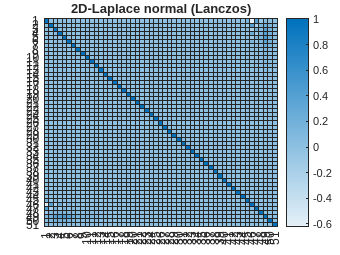

r = rand(N^2,1);
A = gallery('poisson',N);
[V,T] = lanczos(A,r,m);
heatmap(V'*V)
title("2D-Laplace normal (Lanczos)")

% check Lemma 6.4
disp(norm(V(:,1:m)'*A*V(:,1:m) - T(1:m,:)))

    7.8257




disp(norm(A*V(:,1:m) - V(:,1:m+1)*T,'inf'))

   1.8804e-15



heatmap(V'*V - eye(m+1))

% b) 
% run Arnoldi-Verfahren Alg. 6.3 des Skripts
rng(0); %seed
N = 8

N = 8

m = 40

m = 40

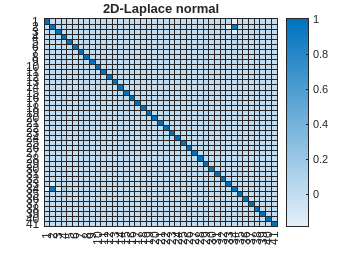

r = rand(N^2,1);
A1 = gallery('poisson',N);
A2 = konv_diff(N,1e-10);

[V1,T1] = arnoldi(A1,r,m);
[V2,T2] = arnoldi(A2,r,m);

heatmap(V1'*V1)
title("2D-Laplace normal")

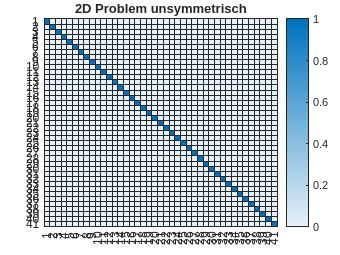

heatmap(V2'*V2)
title("2D Problem unsymmetrisch")

disp(norm(A1*V1(:,1:m) - V1*T1,'inf'))

   4.1606e-15



disp(norm(A2*V2(:,1:m) - V2*T2,'inf'))

   6.7198e-26



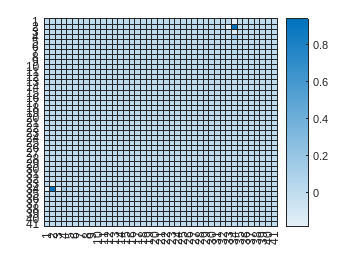

heatmap(V1'*V1 - eye(m+1))

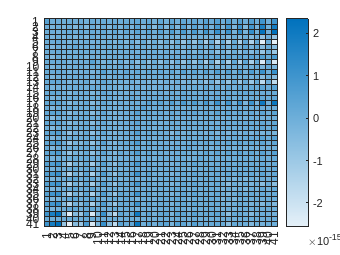

heatmap(V2'*V2 - eye(m+1))

% c) % fehlerhaft ?? T muss auch geupdatet werden
rng(0); %seed
N = 5

N = 5

m = 18

m = 18

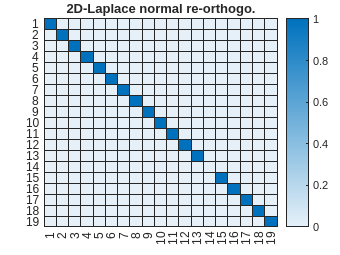

r = rand(N^2,1);
A1 = gallery('poisson',N);
A2 = konv_diff(N,1e-16);

[V1,T1] = arnoldi_re_orthogonalisierung(A1,r,m);
[V2,T2] = arnoldi_re_orthogonalisierung(A2,r,m);

heatmap(V1'*V1)
title("2D-Laplace normal re-orthogo.")

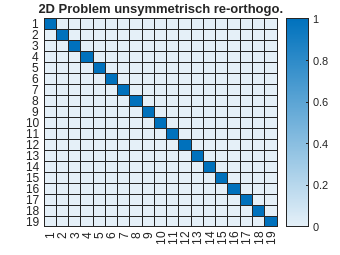

heatmap(V2'*V2)
title("2D Problem unsymmetrisch re-orthogo.")

disp(norm(A1*V1(:,1:m) - V1*T1,'inf'))

    1.7059



disp(norm(A2*V2(:,1:m) - V2*T2,'inf'))

   1.1639e-30



Aufgabe 8:

a) Matrix V bleibt gleich, die Diagonale der Tridiagonalmatrix wird mit alpha addiert

b) 

rng(0); %seed
N = 3

N = 3

m = 5

m = 5

alpha = 6;
r = rand(N^2,1);
A = gallery('poisson',N);
A_tilde = gallery('poisson',N) + alpha*eye(N^2);

A2 = konv_diff(N,1e-16);
A2_tilde = konv_diff(N,1e-16) + alpha*eye(N^2);

[V,T] = lanczos(A,r,m);
[V_tilde,T_tilde] = lanczos(A_tilde,r,m);
disp(norm(V-V_tilde))

    0.7164



disp(T_tilde-T)

    6.0000    0.0000         0         0         0
    0.0000    6.0000   -0.0000         0         0
         0   -0.0000    6.0000   -0.0000         0
         0         0   -0.0000    6.0000    0.0000
         0         0         0    0.0000    6.0000
         0         0         0         0    0.0000



[V1,T1] = arnoldi(A2,r,m);
[V1_tilde,T1_tilde] = arnoldi(A2_tilde,r,m);
disp(V1-V1_tilde)

         0    0.4790   -0.1689   -0.2093   -0.6731   -0.2751
         0   -0.2802   -0.7848    0.4205   -0.5519    0.7504
         0    0.6866    0.3354   -0.0022    0.5501   -0.2459
         0    0.2360   -0.5591    0.2914   -0.0511    0.0440
         0   -0.4524   -0.1079   -0.1382   -0.9236    0.4166
         0   -0.0373    0.4364   -0.5978    0.0564    0.2866
         0    0.1123    0.4890    0.1229   -0.1556    0.5590
         0    0.4649   -0.4282   -0.4737   -0.2881   -0.9164
         0   -0.3216   -0.5902   -0.1055   -0.2097   -0.4286



disp(T1-T1_tilde)

   -6.0000    0.3792   -5.9880    0.0141   -5.9880
    0.0000   -5.9760   -0.3784    0.0009   -0.3784
         0   -0.3784   -0.0240    0.0001   -0.0240
         0         0   -0.0000   -6.0000   -0.0141
         0         0         0   -0.0141   -0.0000
         0         0         0         0   -0.0000

